# Initialize

clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;

singleFilterPlot = nFilters; 


### Loop

n_loops = 5;

for iter = 1:n_loops
    n_plot = 0;


### Variances

    %% Ql %%
    Ql_sigma = 0.377; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0.27;% .* Ql_target ./ 500; % Relative variance of f0, normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = Ql_target - 1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_scattered = zeros(num_elem,nFilters);
    f0_scattered = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
        Ql_sigma = Ql_sigma ./ sqrt(2);
        f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_scattered(i_elem,:) = Ql_target + Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_scattered(i_elem,Ql_scattered(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_scattered(i_elem,:) = f0 + df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_scattered = repmat(Ql_target + Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_scattered(Ql_scattered < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_scattered = repmat(f0 + df .* f0_sigma .* randn(1,nFilters),4,1);
    end

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 6.007788 seconds


Section took 4.644220 seconds


Section took 4.636064 seconds


Section took 4.606792 seconds


Section took 4.624455 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 3.456897 seconds


Section took 3.977412 seconds


Section took 3.857321 seconds


Section took 3.242605 seconds


Section took 3.309318 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,f0_scattered,Z0_thru,Z0_KID,Ql_scattered,Qi,ThruLineLosses,sep,singleFilterPlot);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.559254 seconds


Section took 2.487899 seconds


Section took 2.495789 seconds


Section took 2.839078 seconds


Section took 2.518340 seconds


    
    % showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_skyline,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

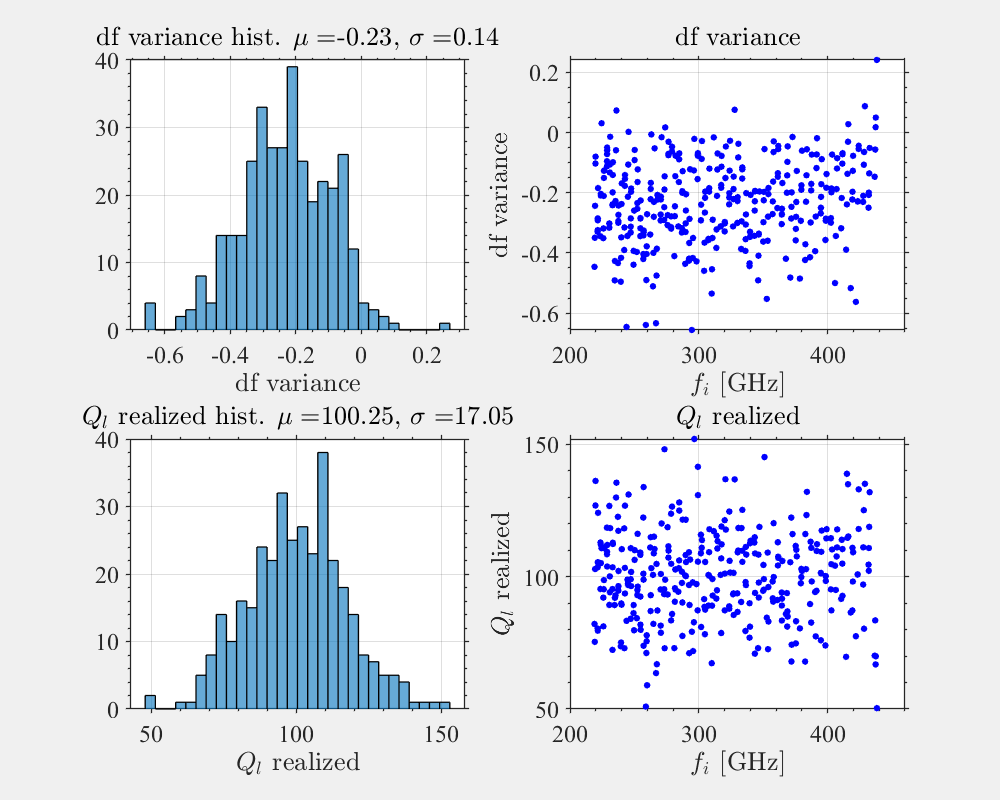

close all; clear functions; %#ok<CLFUNC>
n_plot = 1;
% showFilterBank(f,Data_dir); 
% showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

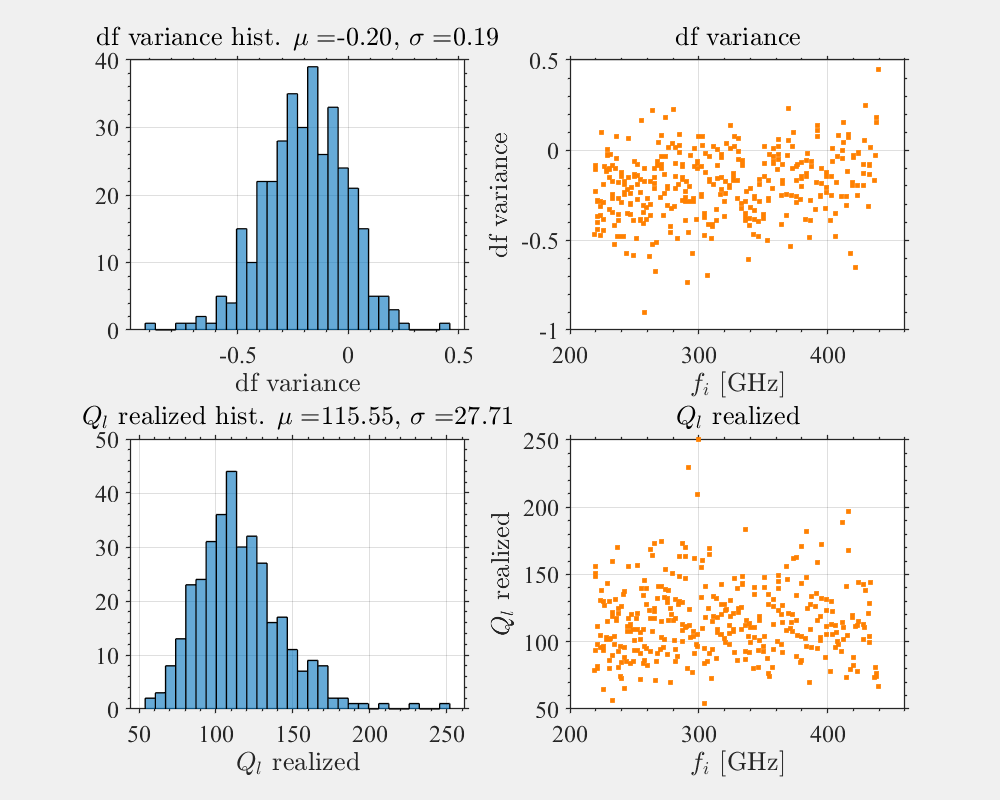


n_plot = 2;
% showFilterBank(f,Data_refl);
% showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

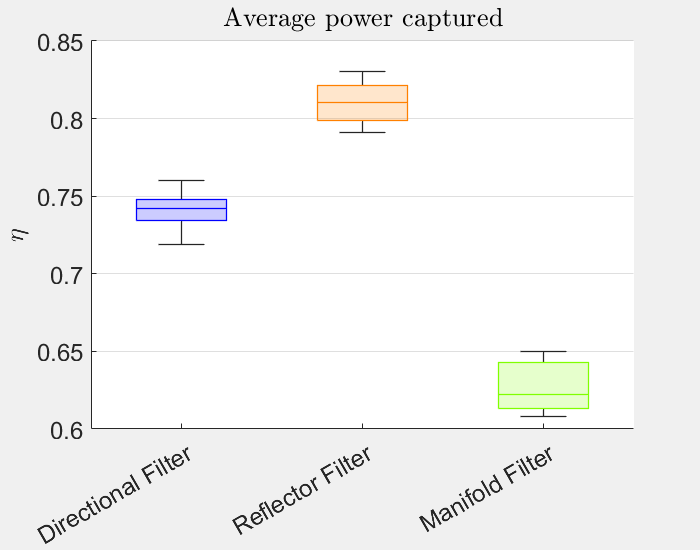

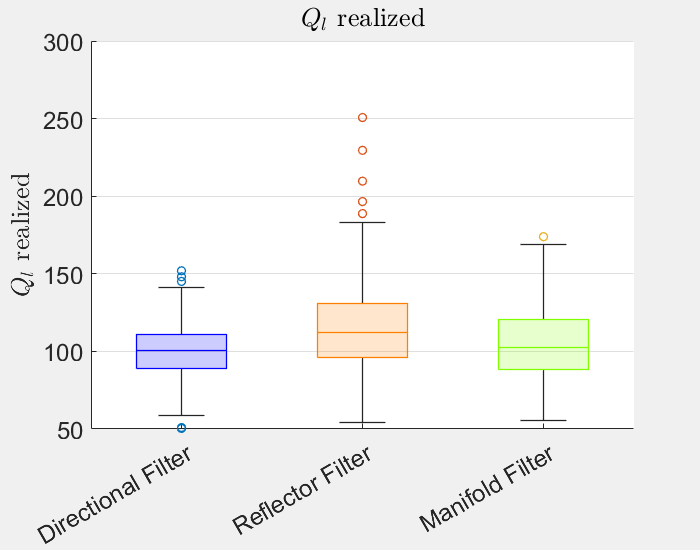

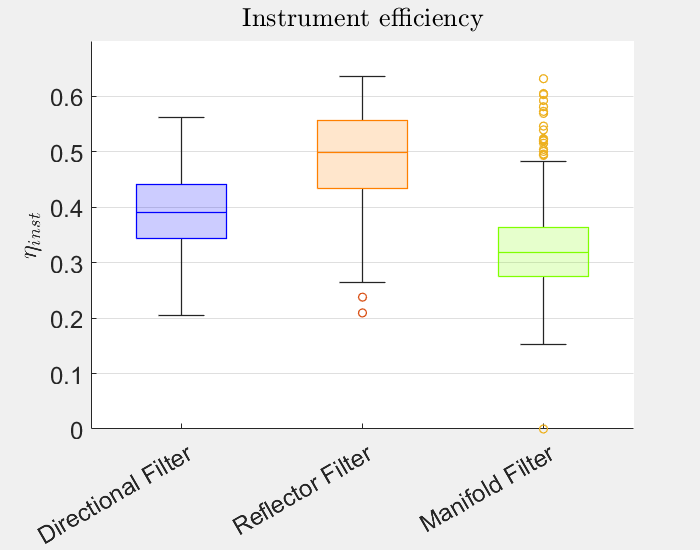

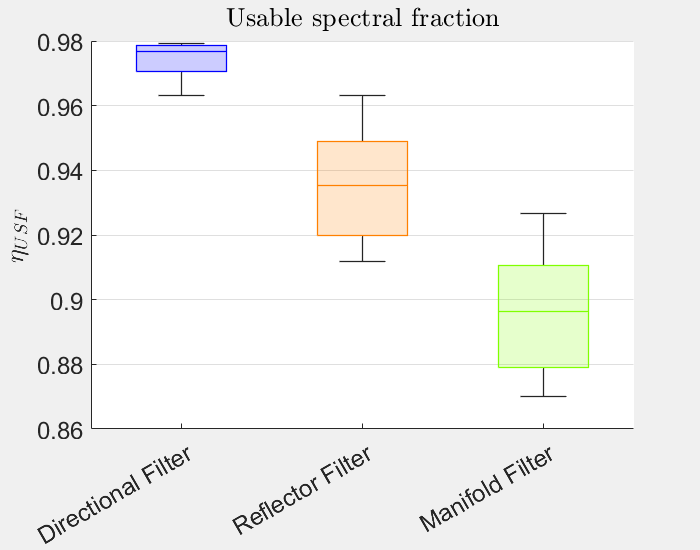

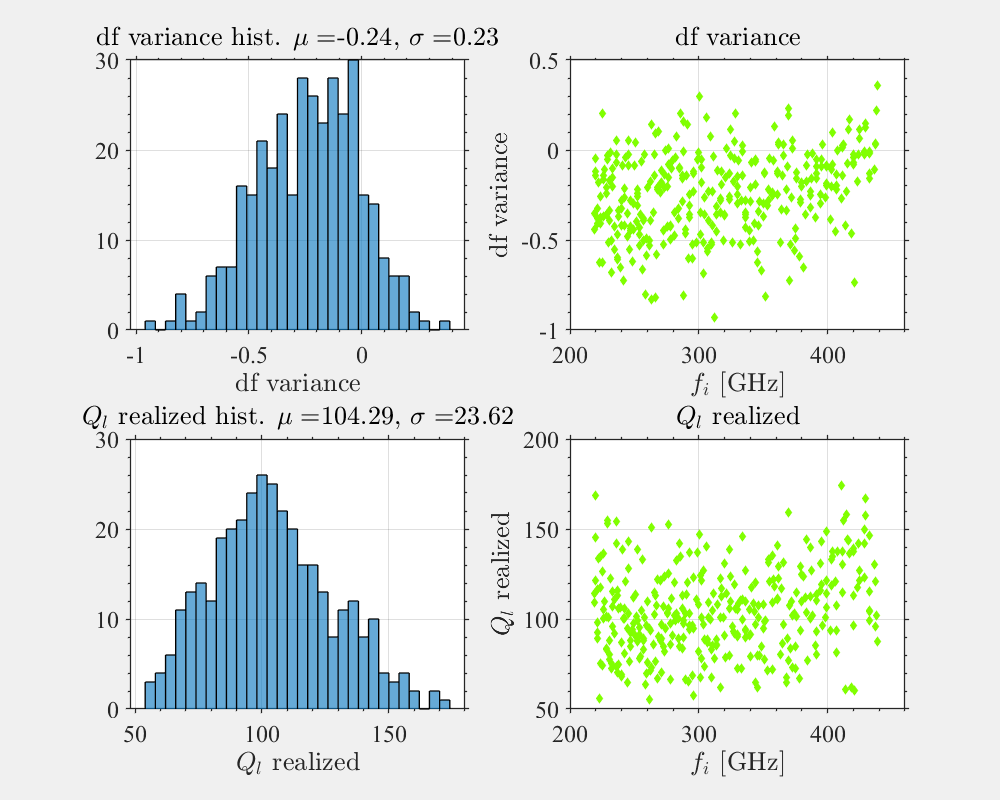



n_plot = 3;
% showFilterBank(f,Data_man);
% showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);



formatPlotting();